**1. Obiekt inercyjny I rzędu:**

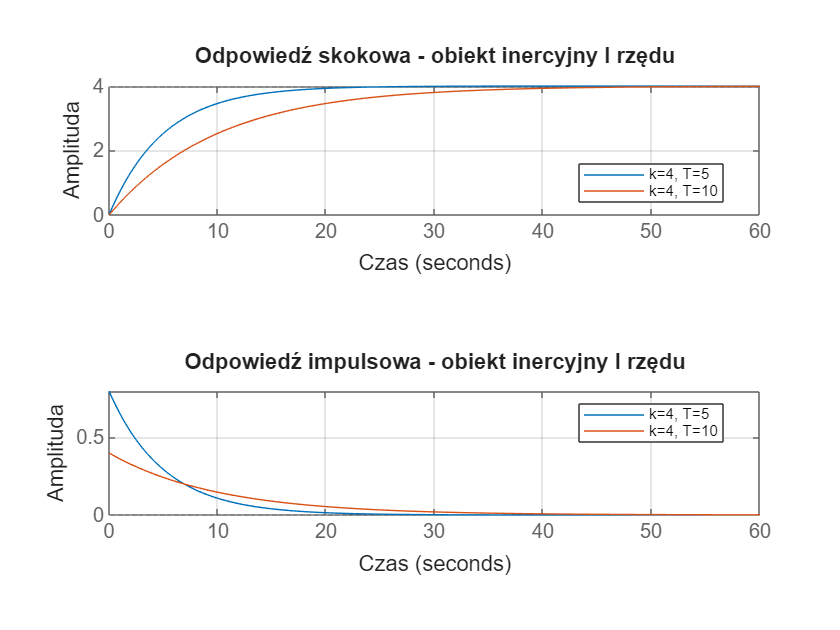

k = 4; 
T1 = 5;
T2 = 10;

licz1 = [k];
mian1 = [T1, 1];
licz2 = [k];
mian2 = [T2, 1];

sys1 = tf(licz1, mian1);
sys2 = tf(licz2, mian2);

figure;
subplot(2,1,1);
step(sys1, sys2);
grid on;
title('Odpowiedź skokowa - obiekt inercyjny I rzędu');
legend(['k=' num2str(k) ', T=5'], ['k=' num2str(k) ', T=10'], 'Location', 'best');
xlabel('Czas');
ylabel('Amplituda');

subplot(2,1,2);
impulse(sys1, sys2);
grid on;
title('Odpowiedź impulsowa - obiekt inercyjny I rzędu');
legend(['k=' num2str(k) ', T=5'], ['k=' num2str(k) ', T=10'], 'Location', 'best');
xlabel('Czas');
ylabel('Amplituda');

**2. Obiekt inercyjny II rzędu:**

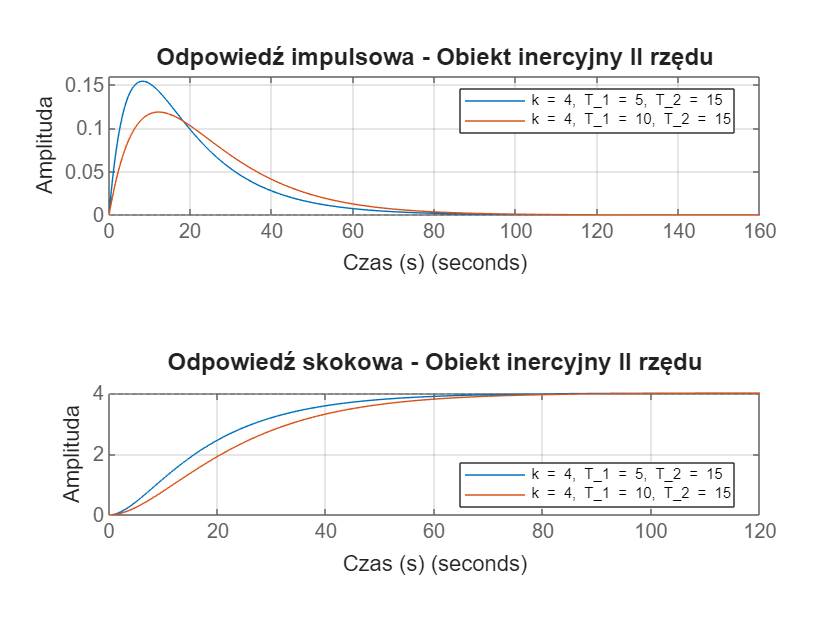

k = 4; 
T1_1 = 5; T2_1 = 15; 
T1_2 = 10; T2_2 = 15; 

licz1 = [k];
mian1 = [T1_1 * T2_1, (T1_1 + T2_1), 1];

licz2 = [k];
mian2 = [T1_2 * T2_2, (T1_2 + T2_2), 1];

sys1 = tf(licz1, mian1);
sys2 = tf(licz2, mian2);

figure;
subplot(2,1,1);
impulse(sys1, sys2);
grid on;
title('Odpowiedź impulsowa - Obiekt inercyjny II rzędu', 'FontSize', 12);
ylabel('Amplituda');
xlabel('Czas (s)');
legend(['k = ', num2str(k), ', T_1 = ', num2str(T1_1), ', T_2 = ', num2str(T2_1)], ...
       ['k = ', num2str(k), ', T_1 = ', num2str(T1_2), ', T_2 = ', num2str(T2_2)], ...
       'Location', 'best');

subplot(2,1,2);
step(sys1, sys2);
grid on;
title('Odpowiedź skokowa - Obiekt inercyjny II rzędu', 'FontSize', 12);
ylabel('Amplituda');
xlabel('Czas (s)');
legend(['k = ', num2str(k), ', T_1 = ', num2str(T1_1), ', T_2 = ', num2str(T2_1)], ...
       ['k = ', num2str(k), ', T_1 = ', num2str(T1_2), ', T_2 = ', num2str(T2_2)], ...
       'Location', 'best');

**3. Obiekt oscylacyjny II rzędu:**

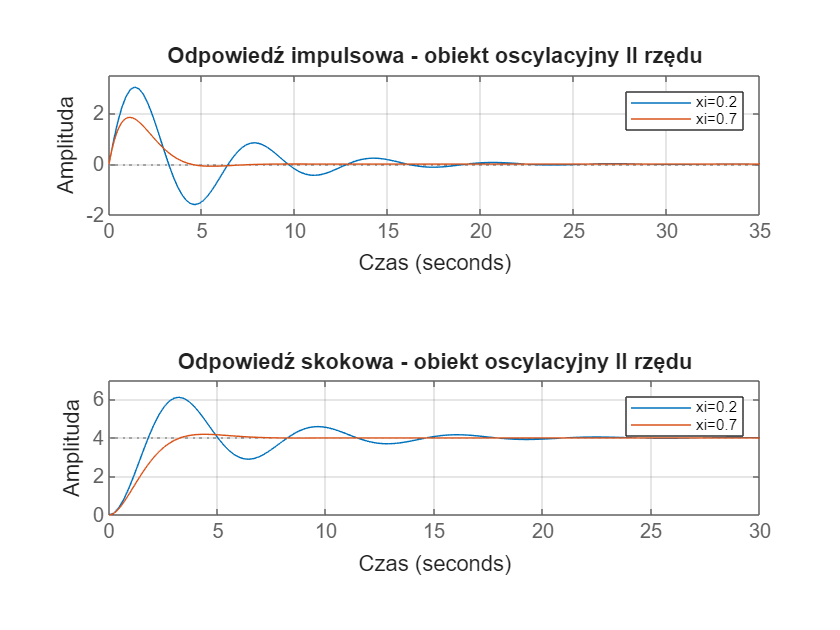

w0 = 1;
k = 4;
xi_1 = 0.2;
xi_2 = 0.7;

licz1 = [k*(w0^2)];
mian1 = [1, 2 * xi_1 * w0, w0^2];
licz2 = [k*(w0^2)];
mian2 = [1, 2 * xi_2 * w0, w0^2];

sys1 = tf(licz1, mian1);
sys2 = tf(licz2, mian2);

figure;
subplot(2,1,1);
impulse(sys1, sys2);
grid on;
title('Odpowiedź impulsowa - obiekt oscylacyjny II rzędu');
legend('xi=0.2', 'xi=0.7');
xlabel('Czas');
ylabel('Amplituda');


subplot(2,1,2);
step(sys1, sys2);
grid on;
title('Odpowiedź skokowa - obiekt oscylacyjny II rzędu');
xlabel('Czas');
ylabel('Amplituda');
legend('xi=0.2', 'xi=0.7');

**4. Obiekt całkujący z inercją I rzędu:**

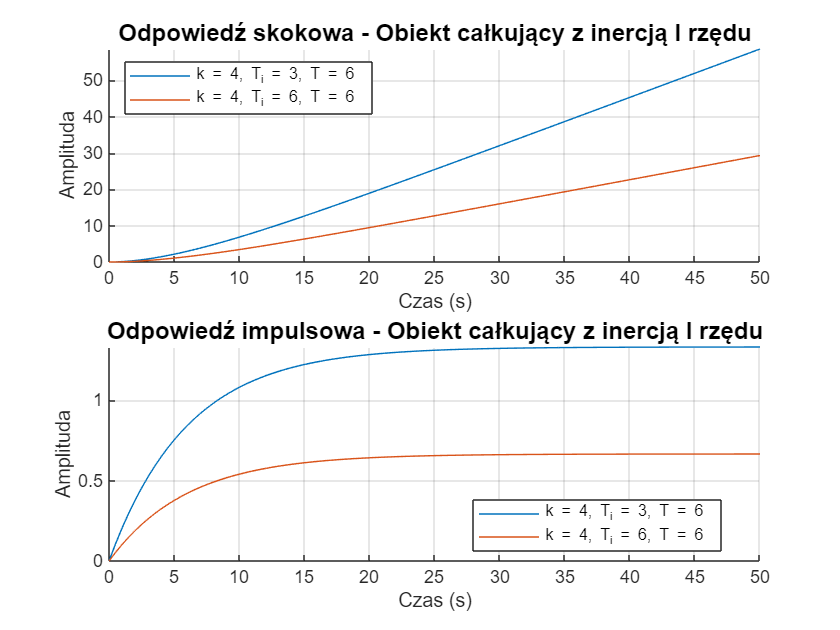

k = 4; 

Ti1 = 3;
T1 = 6;

Ti2 = 6;
T2 = 6;

licz1 = [k];
mian1 = [Ti1*T1, Ti1, 0];

licz2 = [k];
mian2 = [Ti2*T2, Ti2, 0];

sys1 = tf(licz1, mian1);
sys2 = tf(licz2, mian2);

figure;

subplot(2,1,1);
hold on;
[y1, t1] = step(sys1, 50);
[y2, t2] = step(sys2, 50);
plot(t1, y1);
plot(t2, y2);
hold off;
grid on;
title('Odpowiedź skokowa - Obiekt całkujący z inercją I rzędu', 'FontSize', 12);
ylabel('Amplituda');
xlabel('Czas (s)');
legend(['k = ', num2str(k), ', T_i = ', num2str(Ti1), ', T = ', num2str(T1)], ...
       ['k = ', num2str(k), ', T_i = ', num2str(Ti2), ', T = ', num2str(T2)], ...
       'Location', 'northwest');
ylim([0 max([max(y1), max(y2)])]);
xlim([0 50]);

subplot(2,1,2);
hold on;
[y1, t1] = impulse(sys1, 50);
[y2, t2] = impulse(sys2, 50);
plot(t1, y1);
plot(t2, y2);
hold off;
grid on;
title('Odpowiedź impulsowa - Obiekt całkujący z inercją I rzędu', 'FontSize', 12);
ylabel('Amplituda');
xlabel('Czas (s)');
legend(['k = ', num2str(k), ', T_i = ', num2str(Ti1), ', T = ', num2str(T1)], ...
       ['k = ', num2str(k), ', T_i = ', num2str(Ti2), ', T = ', num2str(T2)], ...
       'Location', 'best');
ylim([0 max([max(y1), max(y2)])]); 

**5. Obiekt różniczkujący rzeczywisty:**

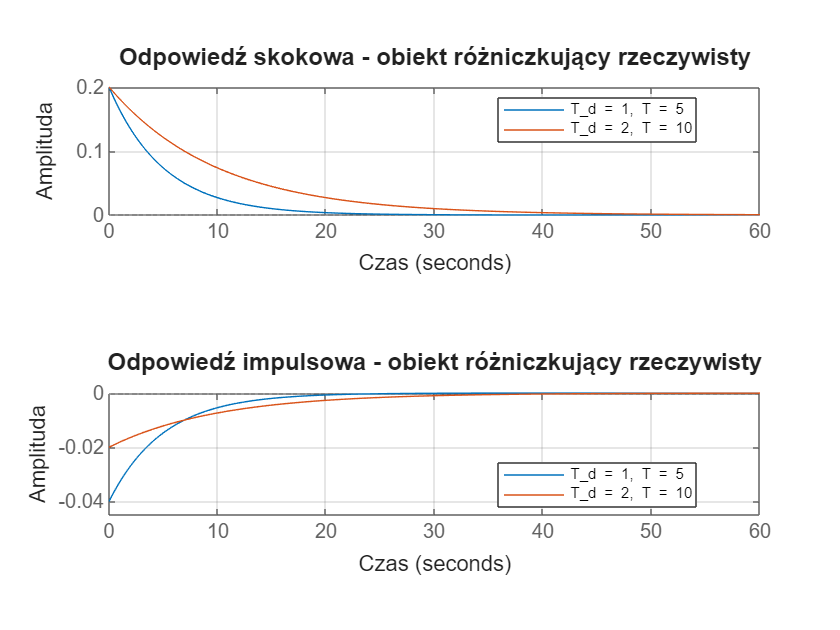

Td1 = 1;
T1 = 5;

Td2 = 2;
T2 = 10;

licz1 = [Td1, 0];
mian1 = [T1, 1];

licz2 = [Td2, 0];
mian2 = [T2, 1];

sys1 = tf(licz1, mian1);
sys2 = tf(licz2, mian2);

figure;
subplot(2,1,1);
step(sys1, sys2);
grid on;
title('Odpowiedź skokowa - obiekt różniczkujący rzeczywisty', 'FontSize', 12);
ylabel('Amplituda');
xlabel('Czas');
legend(['T_d = ', num2str(Td1), ', T = ', num2str(T1)], ...
       ['T_d = ', num2str(Td2), ', T = ', num2str(T2)], ...
       'Location', 'best');

subplot(2,1,2);
impulse(sys1, sys2);
grid on;
title('Odpowiedź impulsowa - obiekt różniczkujący rzeczywisty', 'FontSize', 12);
ylabel('Amplituda');
xlabel('Czas');
legend(['T_d = ', num2str(Td1), ', T = ', num2str(T1)], ...
       ['T_d = ', num2str(Td2), ', T = ', num2str(T2)], ...
       'Location', 'best');

**6. Obiekt inercyjny I rzędu z opóźnieniem:**

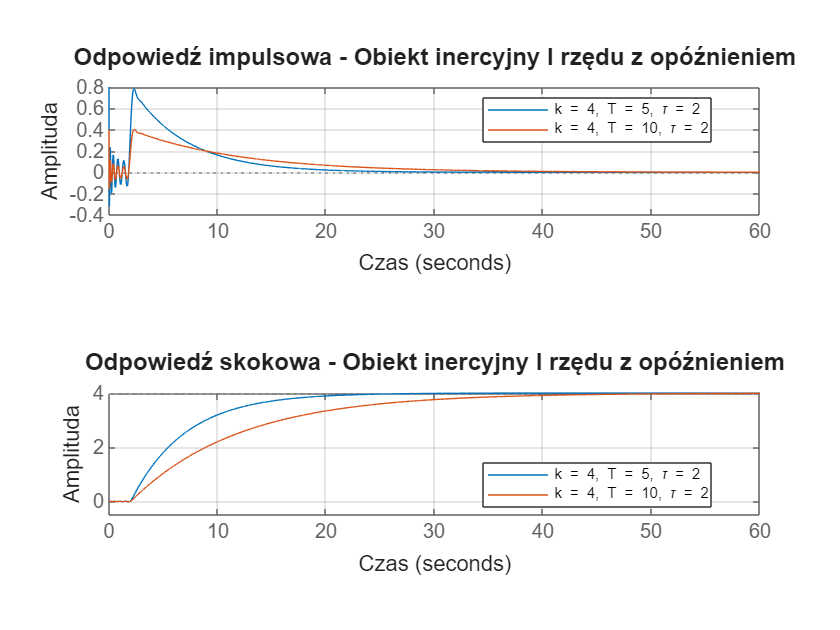

tau = 2; 
n = 10;

[del_l, del_m] = pade(tau, n);

k = 4;
T1 = 5;
T2 = 10;

licz1 = [k];
mian1 = [T1, 1];

licz2 = [k];
mian2 = [T2, 1];

[licz_d1, mian_d1] = series(del_l, del_m, licz1, mian1);
[licz_d2, mian_d2] = series(del_l, del_m, licz2, mian2);

sys1 = tf(licz_d1, mian_d1);
sys2 = tf(licz_d2, mian_d2);

figure;
subplot(2,1,1);
impulse(sys1, sys2);
grid on;
title('Odpowiedź impulsowa - Obiekt inercyjny I rzędu z opóźnieniem', 'FontSize', 12);
ylabel('Amplituda');
xlabel('Czas');
legend(['k = ', num2str(k), ', T = ', num2str(T1), ', \tau = ', num2str(tau)], ...
       ['k = ', num2str(k), ', T = ', num2str(T2), ', \tau = ', num2str(tau)], ...
       'Location', 'best');

subplot(2,1,2);
step(sys1, sys2);
grid on;
title('Odpowiedź skokowa - Obiekt inercyjny I rzędu z opóźnieniem', 'FontSize', 12);
ylabel('Amplituda');
xlabel('Czas');
legend(['k = ', num2str(k), ', T = ', num2str(T1), ', \tau = ', num2str(tau)], ...
       ['k = ', num2str(k), ', T = ', num2str(T2), ', \tau = ', num2str(tau)], ...
       'Location', 'best');